clear;clc

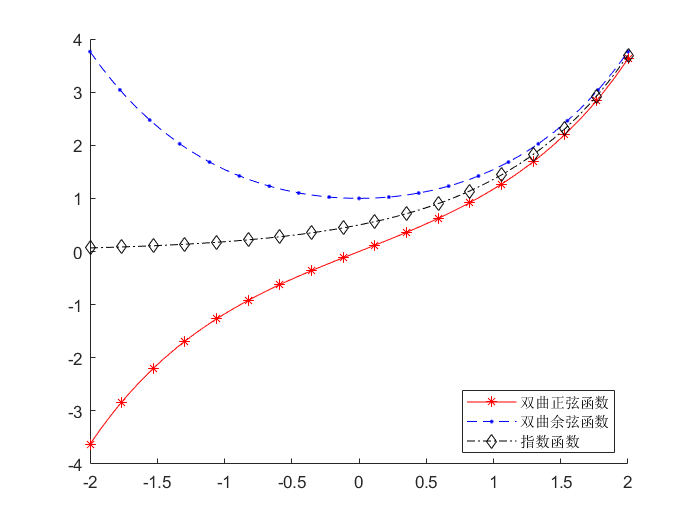

hold on
fplot(@(x)sinh(x),'r-*',[-2,2]);
fplot(@(x)cosh(x),'--.b',[-2,2]);
fplot(@(x)1/2*exp(x),'-.dk',[-2,2])
legend('双曲正弦函数','双曲余弦函数','指数函数','Location','best')
hold off

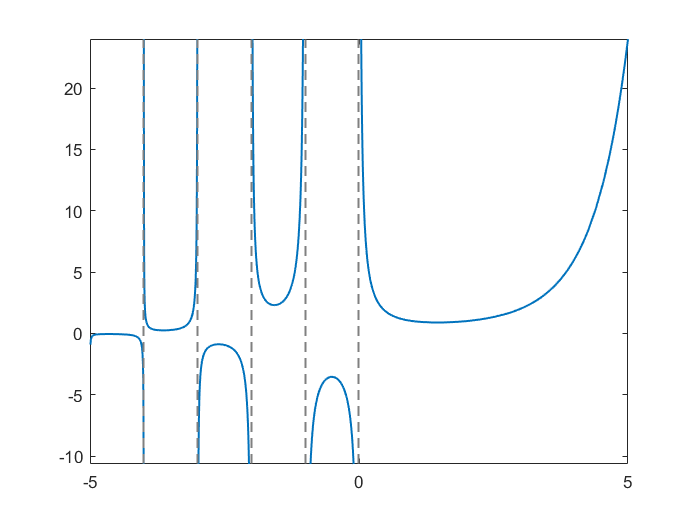

fplot(@(x)gamma(x),'LineWidth',1.2)
hold off

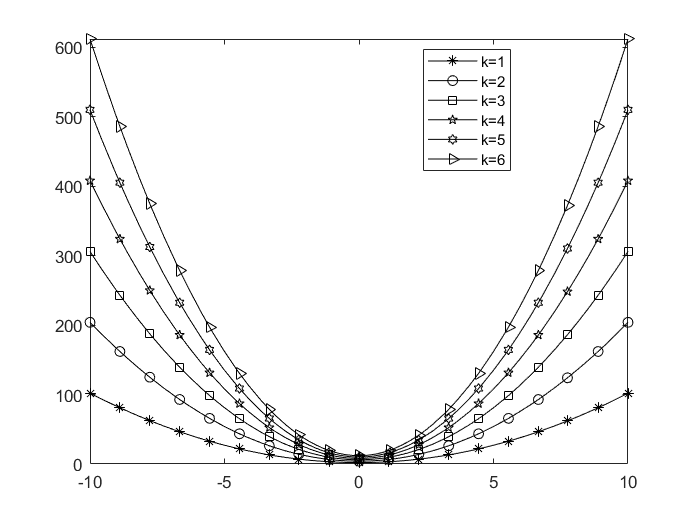

fx=@(x,k)k*x.^2+2*k;
str1={'*k-','ok-','sk-','pk-','Hk-','>k-'};
for k=1:6
    fplot(@(x)fx(x,k),str1{k},[-10,10])
    hold on
end
str2=strcat('k=',int2str([1:6]'));
legend(str2,'Location','best')
hold off

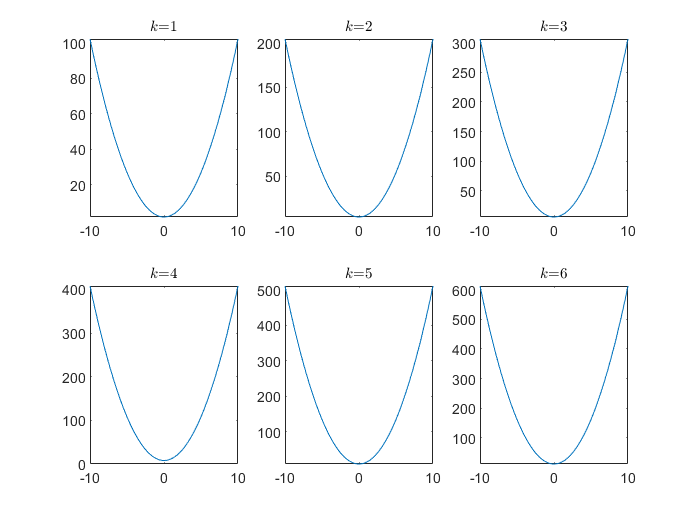

clc, clear, close all
fx=@(x,k)k*x.^2+2*k;
str=strcat('$k$=',int2str([1:6]'));
for k=1:6
    subplot(2,3,k)
    fplot(@(x)fx(x,k),[-10,10])
    title(str(k,:),'Interpreter','Latex')
end

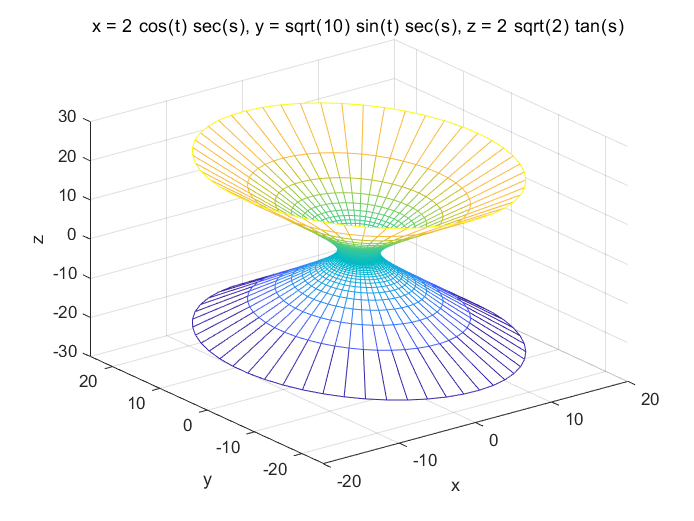

clc, clear, close all
x=@(t,s)2*cos(t).*sec(s);  
y=@(t,s)sqrt(10)*sin(t).*sec(s);
z=@(t,s)2*sqrt(2)*tan(s);  
ezmesh(x,y,z,[0,2*pi,-pi/2,pi/2])

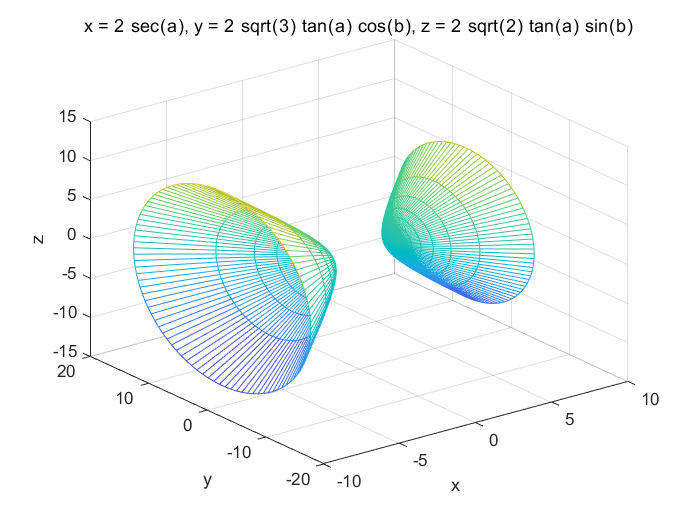

clc, clear, close all
x=@(a,b)2*sec(a);  
y=@(a,b)2*sqrt(3)*tan(a).*cos(b);
z=@(a,b)2*sqrt(2)*tan(a).*sin(b);  
ezmesh(x,y,z,[0,2*pi,0,pi])

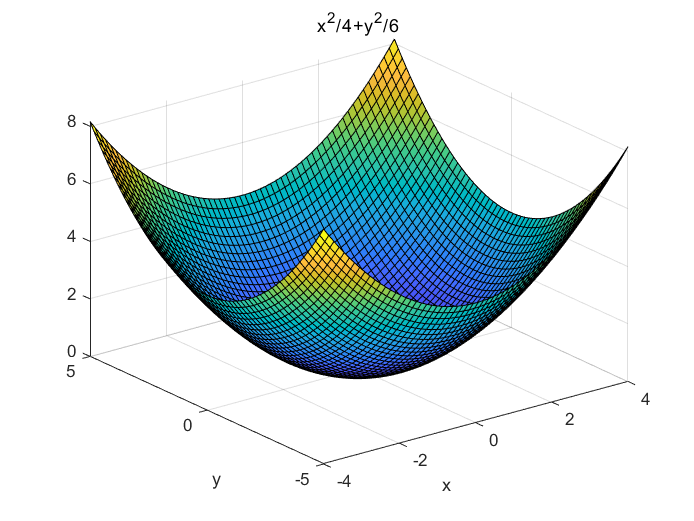

clc, clear, close all
z=@(x,y)x.^2/4+y.^2/6;
ezsurf(z,[-4,4,-5,5])